## Encontrar objetos transparentes por medio de su fase

Se lee la imagen sin mucha información de intensidad, pero si de fase

purePhase = readmatrix("a.dat")

purePhase =    0.9882 + 0.1534i   0.9916 + 0.1290i   0.9957 + 0.0923i   0.9968 + 0.0800i   0.9977 + 0.0677i   0.9991 + 0.0431i   1.0000 - 0.0062i   0.9991 - 0.0431i   0.9985 + 0.0554i   0.9991 - 0.0431i   0.9945 - 0.1045i   0.9991 - 0.0431i   0.9957 + 0.0923i   0.9900 + 0.1412i   0.9985 + 0.0554i   0.9977 - 0.0677i   1.0000 - 0.0062i   0.9991 + 0.0431i   0.9957 + 0.0923i   0.9968 + 0.0800i   1.0000 + 0.0062i   0.9957 - 0.0923i   0.9841 - 0.1777i   0.9768 - 0.2139i   0.9977 - 0.0677i   0.9957 - 0.0923i   0.9977 - 0.0677i   1.0000 - 0.0062i   0.9998 + 0.0185i   1.0000 - 0.0062i   1.0000 + 0.0062i   0.9985 + 0.0554i   0.9977 + 0.0677i   0.9968 + 0.0800i   0.9945 + 0.1045i   0.9882 + 0.1534i   0.9841 + 0.1777i   0.9862 + 0.1656i   0.9932 + 0.1168i   0.9977 + 0.0677i   0.9968 + 0.0800i   0.9957 + 0.0923i   0.9945 + 0.1045i   0.9916 + 0.1290i   0.9900 + 0.1412i   0.9882 + 0.1534i   0.9862 + 0.1656i   0.9841 + 0.1777i   0.9900 + 0.1412i   0.9900 + 0.1412i
   0.9916 + 0.1290i   0.9932 + 0.1168

[h,w] = size(purePhase);

Se puede ver que esta imagen no contiene mucha información en su perfil de intensidad

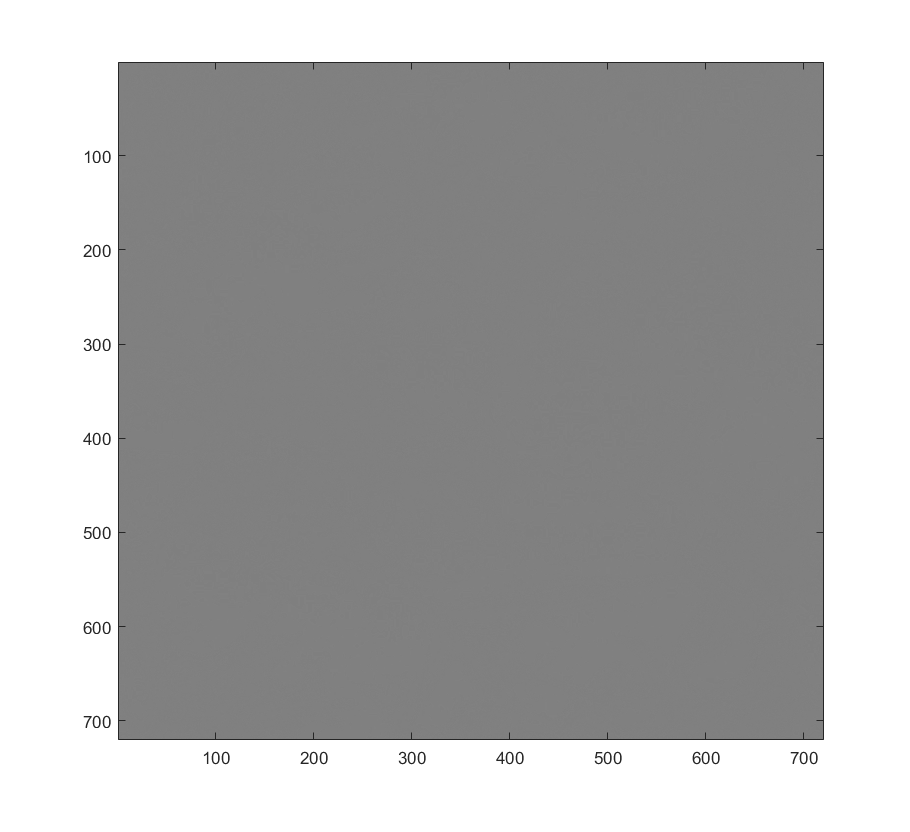

imagesc(abs(purePhase).^2)
colormap('gray')

La imagen es completamente blanca.

A continuación se observa la distribución de angulos de fase de la matriz revelando su contenido 

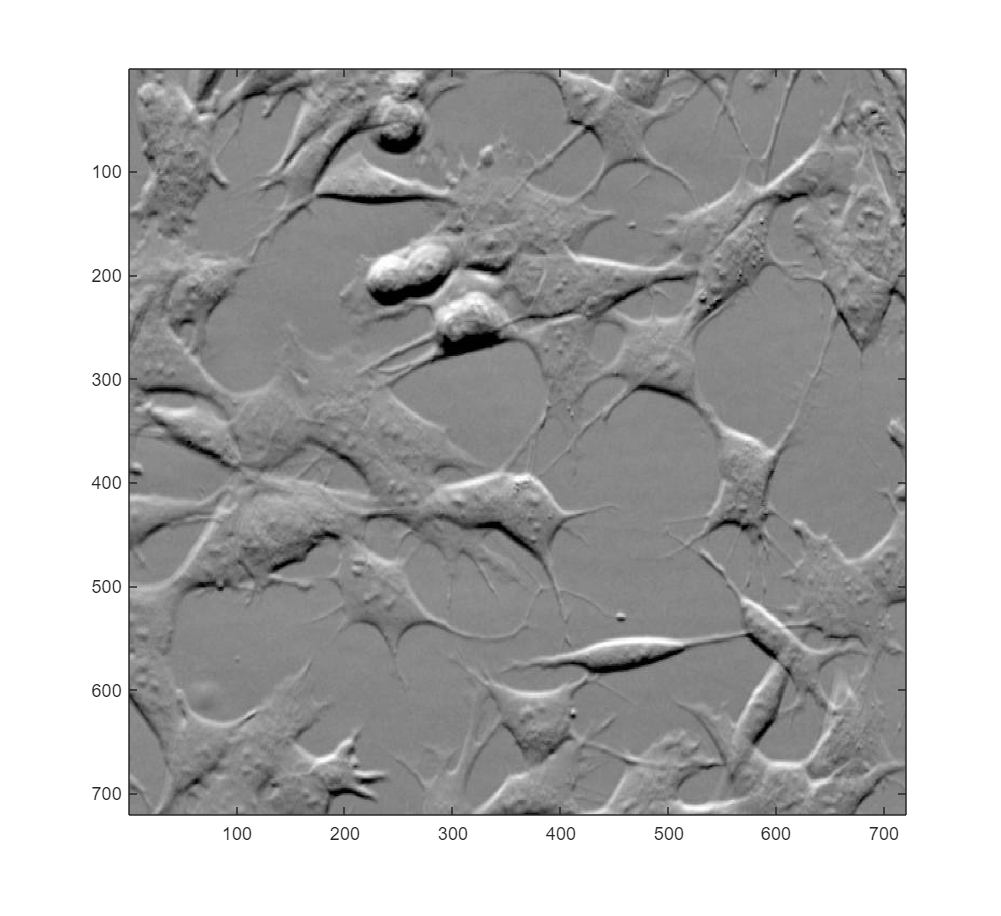

imagesc((angle(purePhase)))

Observemos la transformada de fourier de esta distribución 

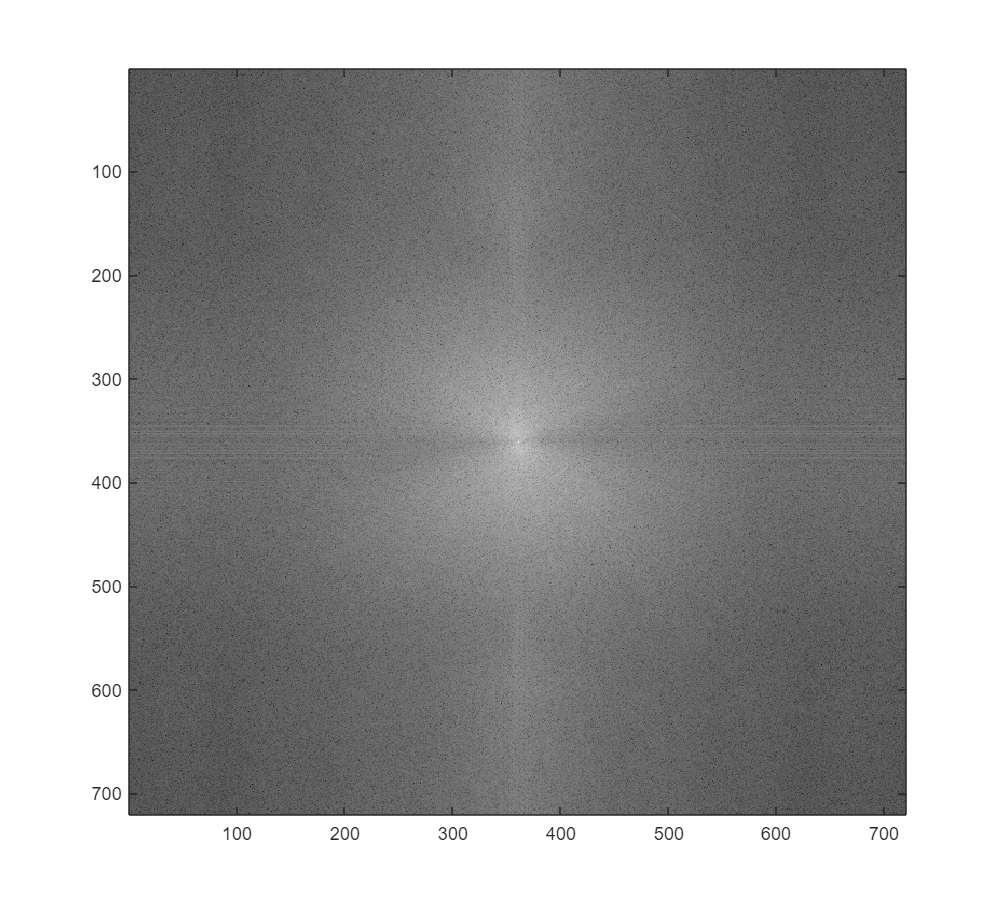

purePhaseFT = fft2(purePhase);
imagesc(log(abs(fftshift(fourierTransform))))

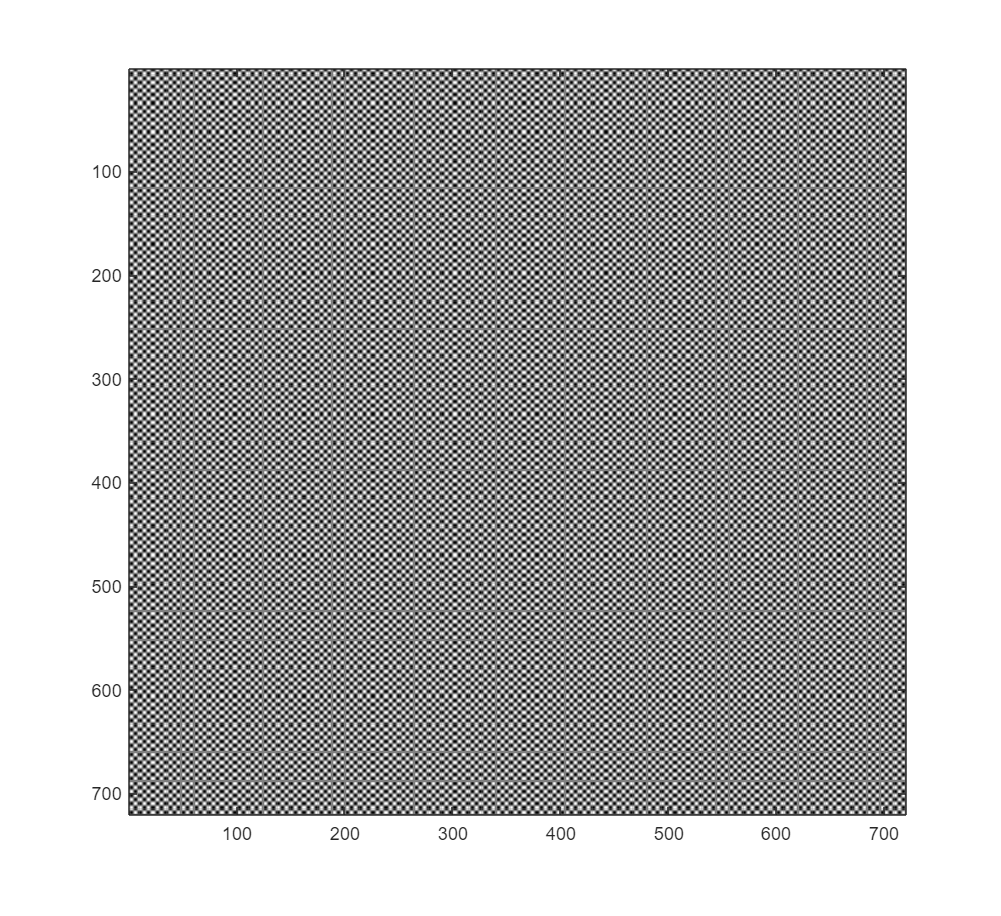

radioFiltro = 5;
frecuencia = 8;
filtro = plane_wave2D(frecuencia,90,0,1:w,1:h).* plane_wave2D(frecuencia,0,0,1:w,1:h);
imagesc(filtro)

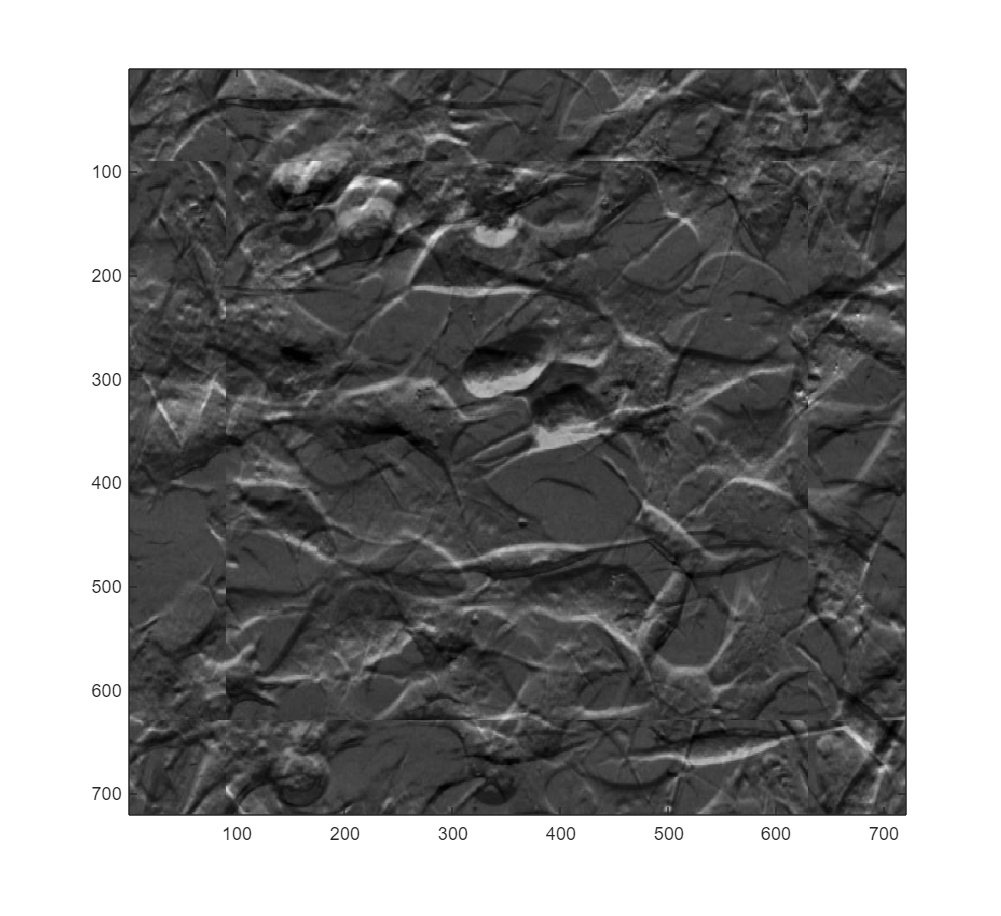

[~,imagenFiltrada] = sistema4f(purePhase,filtro);
imagesc((imrotate(imagenFiltrada,180)))